# Laborator 1

## Problema 1

Calculați cel mai apropiat număr real pozitiv de zero. Comparați cu valoarea lui *realmin* din MATLAB. Ce observați? Explicați.

format long
eps(0)

ans =     4.940656458412465e-324


realmin

ans =     2.225073858507201e-308


myeps

ans =      2.220446049250313e-16


myeps0

ans =     4.940656458412465e-324


## Problema 2

Calculați cu o eroare dată *err*:


$$\sinh \;x=x+\frac{x^3 }{3!}+\frac{x^5 }{5!}+\ldotp \ldotp \ldotp +\frac{x^{2n+1} }{\left(2n+1\right)!}+\ldotp \ldotp \ldotp$$



$$\cosh \;x=1+\frac{x^2 }{2!}+\frac{x^4 }{4!}+\ldotp \ldotp \ldotp +\frac{x^{2n} }{\left(2n\right)!}+\ldotp \ldotp \ldotp$$


Cu ce eroare se poate aproxima $\tanh \;x=\frac{\sinh \;x}{\cosh \;x}$ știind că $\sinh \;x$ și $\cosh \;x$ au fost aproximate cu eroarea *err*?

err1=10^(-7);
t=0.5;
errAbs(tanh(t),mySinh(t,err1)./myCosh(t,err1))

ans =      9.963074809604677e-11


errRel(tanh(t),mySinh(t,err1)./myCosh(t,err1))

ans =      2.155962974557762e-10



err1=10^(-23);
t=pi/37;
errAbs(tanh(t),mySinh(t,err1)./myCosh(t,err1))

ans =      1.387778780781446e-17


errRel(tanh(t),mySinh(t,err1)./myCosh(t,err1))

ans =      1.638377604659516e-16


## Problema 3

Fie problema bilocală:

${y^{\prime } }^{\prime } \left(x\right)-y\left(x\right)=e^x ,y\left(0\right)=\frac{1}{2},y\left(1\right)=e$.

Soluția analitică $y\left(x\right)=\frac{1}{2}e^x \left(x+1\right)$ se poate obține cu Mathematica.

Rezolvați analitic (folosind o discretizare cu diferențe finite) ecuația diferențială folosind 11 noduri, 51 de noduri și 101 noduri. Calculați erorile absolute și relative în fiecare caz.

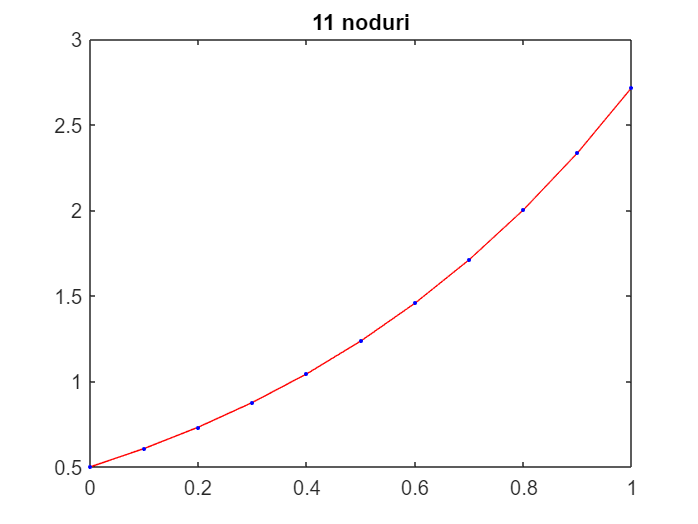

figure (1)
N=11;
a=0;
b=1;
h=(b-a)/(N-1);
A=zeros(N,N);
A(1,1)=1;
i=2;
while i+1<N
    A(i,i-1)=1;
    A(i,i)=-(2+h^2);
    A(i,i+1)=1;
    i=i+1;
end
A(N-1,N-2)=1;
A(N-1,N-1)=-(2+h^2);
A(N-1,N)=1;
A(N,N)=1;
t=linspace(0,1,11);
c=zeros(N,1);
c(1,1)=1/2;
c(N,1)=exp(1);
for i=2:N-1
    c(i,1)=exp((i-1)*h)*h^2;
end
sol=A\c;
G=1/2*exp(t).*(1+t);
plot(t,G,'r')
hold on
plot(t,sol,'b.')
title('11 noduri')

eA=errAbs(G',sol);
eR=errRel(G',sol);
fprintf('Eroarea absolută este %2.5f',eA)

Eroarea absolută este 0.00044

fprintf('Eroarea relativă este %2.5f',eR)

Eroarea relativă este 0.00016

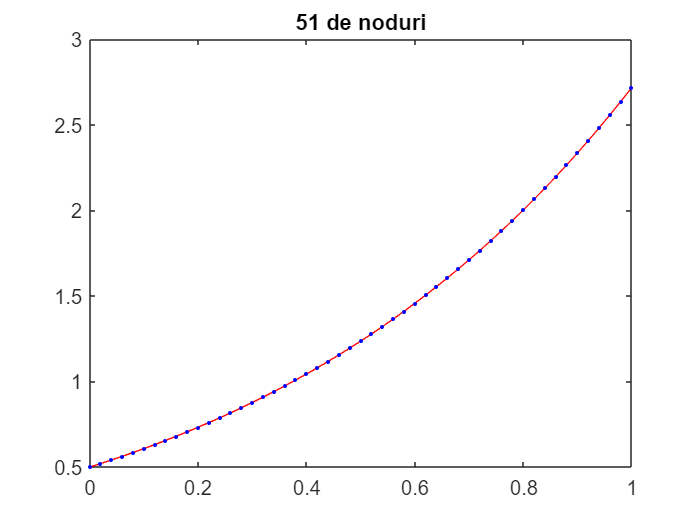


figure (2)
N=51;
a=0;
b=1;
h=(b-a)/(N-1);
A=zeros(N,N);
A(1,1)=1;
i=2;
while i+1<N
    A(i,i-1)=1;
    A(i,i)=-(2+h^2);
    A(i,i+1)=1;
    i=i+1;
end
A(N-1,N-2)=1;
A(N-1,N-1)=-(2+h^2);
A(N-1,N)=1;
A(N,N)=1;
t=linspace(0,1,51);
c=zeros(N,1);
c(1,1)=1/2;
c(N,1)=exp(1);
for i=2:N-1
    c(i,1)=exp((i-1)*h)*h^2;
end
sol=A\c;
G=1/2*exp(t).*(1+t);
plot(t,G,'r')
hold on
plot(t,sol,'b.')
title('51 de noduri')

eA=errAbs(G',sol);
eR=errRel(G',sol);
fprintf('Eroarea absolută este %2.5f',eA)

Eroarea absolută este 0.00002

fprintf('Eroarea relativă este %2.5f',eR)

Eroarea relativă este 0.00001

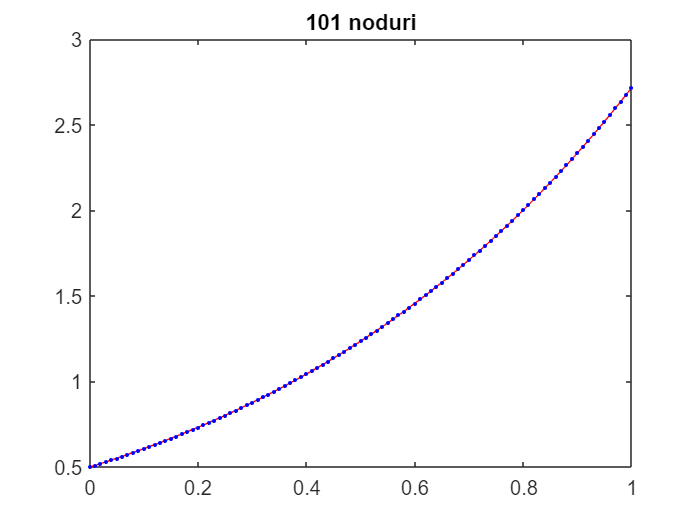


figure (3)
N=101;
a=0;
b=1;
h=(b-a)/(N-1);
A=zeros(N,N);
A(1,1)=1;
i=2;
while i+1<N
    A(i,i-1)=1;
    A(i,i)=-(2+h^2);
    A(i,i+1)=1;
    i=i+1;
end
A(N-1,N-2)=1;
A(N-1,N-1)=-(2+h^2);
A(N-1,N)=1;
A(N,N)=1;
t=linspace(0,1,101);
c=zeros(N,1);
c(1,1)=1/2;
c(N,1)=exp(1);
for i=2:N-1
    c(i,1)=exp((i-1)*h)*h^2;
end
sol=A\c;
G=1/2*exp(t).*(1+t);
plot(t,G,'r')
hold on
plot(t,sol,'b.')
title('101 noduri')

eA=errAbs(G',sol);
eR=errRel(G',sol);
fprintf('Eroarea absolută este %2.5f',eA)

Eroarea absolută este 0.00000

fprintf('Eroarea relativă este %2.5f',eR)

Eroarea relativă este 0.00000

## Funcții utilizate

### myeps

function eps=myeps
    eps = 1;
    while (1+eps) > 1
        eps = eps/2;
    end
    eps = eps*2;   
end

### myeps0

function eps0=myeps0
    x = 1;
    while 0 < x
        eps0=x;
        x = x/2;
    end
end

### mySinh

function [y,ni]=mySinh(x,err,Nmax)

    if nargin<2, err=eps; Nmax=1000; end
    if nargin<3, Nmax=1000; end
    
    S=x;
    T=x;
    for i=1:Nmax    
        %i
       T=T*x^2/(2*i)/(2*i+1);
     %  pause
       S=S+T;
       if T<err*S
          y=S;   
          ni=i;
          return
       end
    end
    y=S;
    error('prea multe iteratii')
end

### myCosh

function [y,ni]=myCosh(x,err,Nmax)
    if nargin<2, err=eps; Nmax=1000; end
    if nargin<3, Nmax=1000; end
    
    S=1;
    T=1;
    for i=1:Nmax    
        %i
       T=T*x^2/(2*i)/(2*i-1);
     %  pause
       S=S+T;
       if T<err*S
          y=S;   
          ni=i;
          return
       end
    end
    y=S;
    error('prea multe iteratii')
end

### errAbs

function err=errAbs(y_e,y)
    err=norm(y_e-y,Inf);
end

### errRel

function err=errRel(y_e,y)
    err=(norm(y_e-y,Inf))./(norm(y_e,Inf));
end